# INME 4012 - Project

# Machine Design

## Scenario: 

A punch press is used to stamp circular steel washers from a workpiece. A schematic of the washer producing device is shown below. A flywheel is directly coupled to a crankshaft. An electric motor drives the crankshaft via a gear reducer. As the motor rotates, a punching die reciprocates producing washers each revolution of the crankshaft. The purpose of the flywheel is to reduce the size of the motor and gearbox necessary to produce these washers. The optimal motor speed is 1000-1,100 RPM. The crankshaft diameter is 55 mm and fabricated from ASTM 1018 annealed steel. In order to meet production demands, 100 disks are produced each minute. The crankshaft torque necessary to stamp each washer is shown in a separate figure below. During “punching”, the flywheel speed is reduced and the energy to reduce the flywheel speed is used to “help” produce the washers. The motor increases the speed of the flywheel during the non-punching region. Also shown below is the flywheel speed variation. 

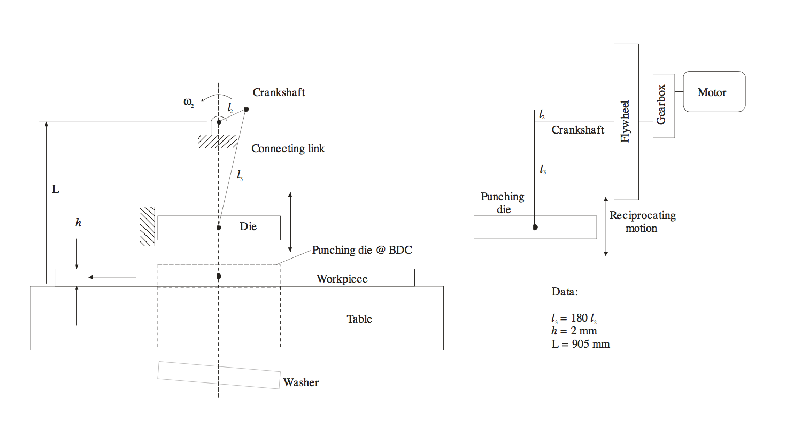

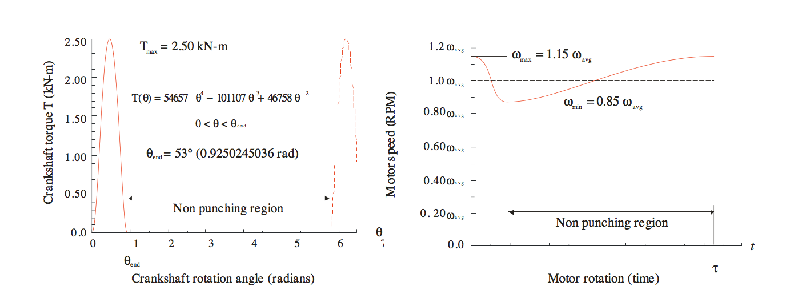

The following information is given:

crankshaftDiameter = 55; % mm
l2 = crankshaftDiameter;
h = 2; % mm
l3 = 180*l2;
L = 905; % mm

The torque can be computed as:

thetaEnd = 53; %deg
fracPress = round(10000*(thetaEnd/360));
fracNoPress = round(10000*((360-thetaEnd)/360));
thetaPress = linspace(0,0.9250245036,fracPress);
torqueEq = @(thetaVar) 54657.*(thetaVar.^4)-101107*(thetaVar.^3)+46758*(thetaVar.^2);
torquePress = torqueEq(thetaPress);
SecondPress = 360-0.5*thetaEnd;
SecondPress = SecondPress*(pi/180);
thetaNoPress = linspace(0.9250245036,SecondPress,fracNoPress+1);
thetaPress2 = linspace(SecondPress,SecondPress+0.9250245036,fracPress);
thetaNoPress2 = linspace(SecondPress+0.9250245036,2*SecondPress,fracNoPress+1);
thetaPress3 = linspace(2*SecondPress,2*SecondPress+0.9250245036,fracPress);
thetaNoPress3 = linspace(2*SecondPress+0.9250245036,3*SecondPress,fracNoPress+1);
thetaPress4 = linspace(3*SecondPress,3*SecondPress+0.9250245036,fracPress);
thetaNoPress4 = linspace(3*SecondPress+0.9250245036,4*SecondPress,fracNoPress+1);
thetaPress5 = linspace(4*SecondPress,4*SecondPress+0.9250245036,fracPress);
thetaNoPress5 = linspace(4*SecondPress+0.9250245036,5*SecondPress,fracNoPress+1);
thetaPress6 = linspace(5*SecondPress,5*SecondPress+0.9250245036,fracPress);

The torque behaves as:

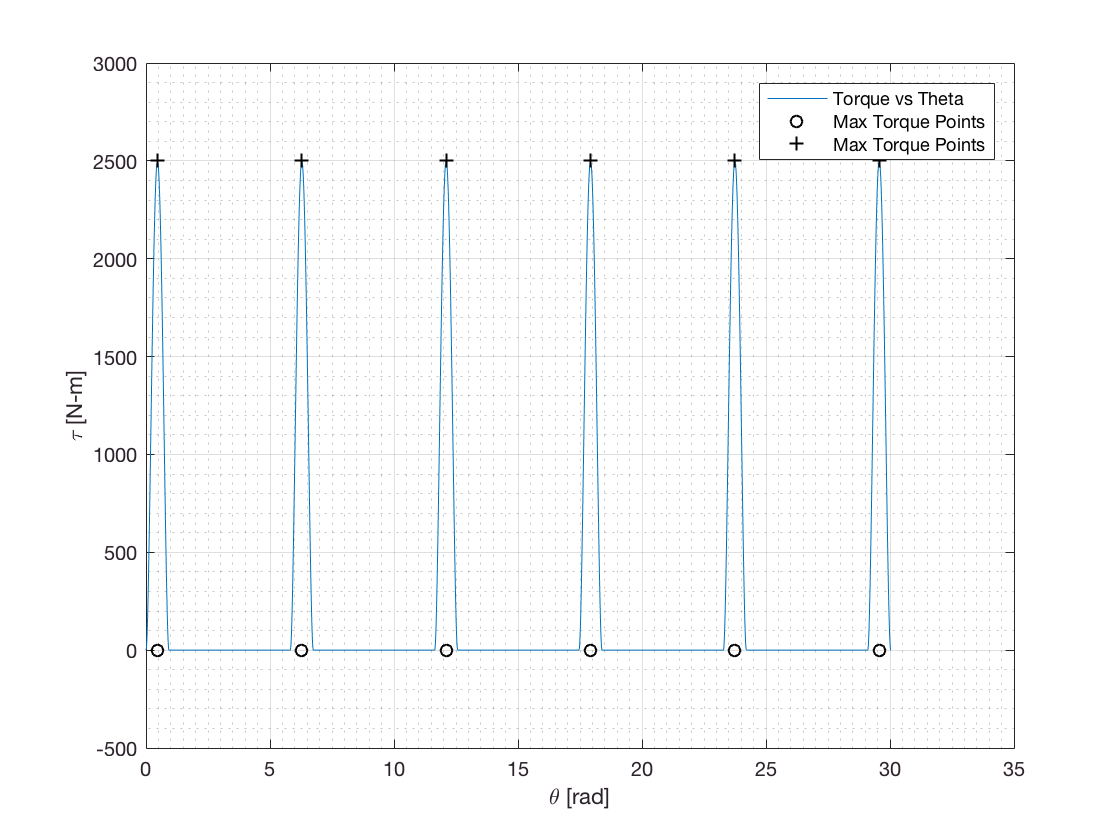

theta = [thetaPress,thetaNoPress,thetaPress2,thetaNoPress2,...
    thetaPress3,thetaNoPress3,thetaPress4,thetaNoPress4,thetaPress5,thetaNoPress5,thetaPress6];
torque = [torquePress,zeros(1,numel(thetaNoPress)),torquePress,...
    zeros(1,numel(thetaNoPress2)),torquePress,zeros(1,numel(thetaNoPress3)),...
    torquePress,zeros(1,numel(thetaNoPress2)),torquePress,zeros(1,numel(thetaNoPress2)),torquePress];
figure('Name','Torque vs Theta')
plot(theta,torque); hold on

scatter([(0.5*0.9250245036),2*pi,4*pi-(0.5*0.9250245036),...
    6*pi-2*(0.5*0.9250245036),8*pi-3*(0.5*0.9250245036),...
    10*pi-4*(0.5*0.9250245036)],[0,0,0,0,0,0],'ko')
scatter([(0.5*0.9250245036),2*pi,4*pi-(0.5*0.9250245036),...
    6*pi-2*(0.5*0.9250245036),8*pi-3*(0.5*0.9250245036),...
    10*pi-4*(0.5*0.9250245036)],[2500,2500,2500,2500,2500,2500],'k+')

legend('Torque vs Theta','Max Torque Points','Max Torque Points')
xlabel('\theta [rad]')
ylabel('\tau [N-m]')
grid on
grid minor

Attempting to determine the punch press' speed, we determine how many radians are required per spike. From this estimate, whose accuracy will increase with more spikes as a cummulative error exists. From the problem statement, we know that 100 disks are required per minute. 

The central point of any spike beyond the third spike can be determined using the following equation:


$$T_{max_{location}}=2(n-1)\pi-(n-2)(\frac{53\pi}{360})$$


The rightmost point can be easily determined by adjusting the second term in the previous equation:


$$T_{max_{location}}=2\pi (n-1)-(n-1)(\frac{53\pi}{360})\\
T_{max_{location}}=(2\pi - (\frac{53\pi}{360}))(n-1)\\
T_{max_{location}} \approx 5.8207(n-1)$$


From this equation we determine the 100th spike location to be:

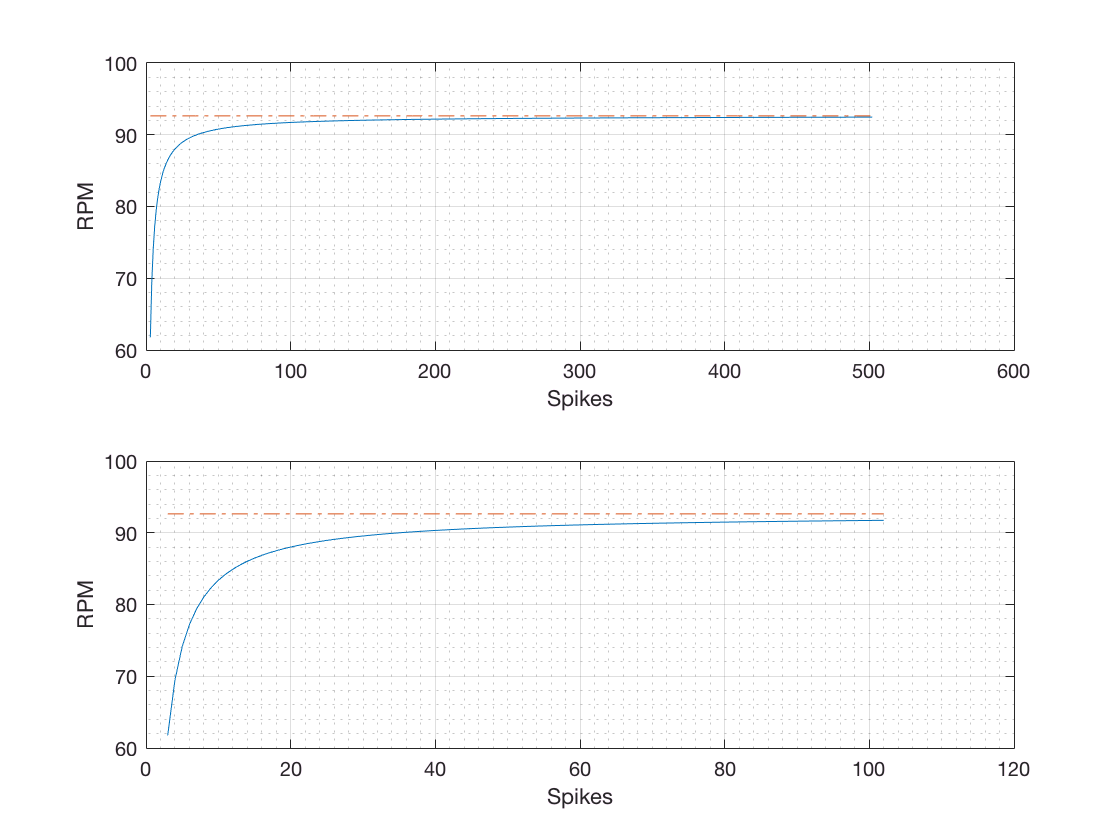

spikes = [3:1000000];
% Here, the full expression is used to facilitate code maintenance.
EstimatedRadians = (2.*(spikes-1).*pi)-((spikes-1).*(0.5*0.9250245036));
EstimatedRevs = EstimatedRadians./(2*pi); % revs
RevsPerSpike = EstimatedRevs./spikes; % revs/spikes
ReqDisks = 100;
RequiredRPMs = RevsPerSpike.*ReqDisks;
figure('Name','EstimatedRevs vs Terms Used')
subplot(2,1,1)
plot(spikes(1:500),RequiredRPMs(1:500)); hold on
plot(spikes(1:500),max(RequiredRPMs).*ones(1,numel(spikes(1:500))),'-.')
xlabel('Spikes')
ylabel('RPM')
grid on 
grid minor
subplot(2,1,2)
plot(spikes(1:100),RequiredRPMs(1:100)); hold on
plot(spikes(1:100),max(RequiredRPMs).*ones(1,numel(spikes(1:100))),'-.')
xlabel('Spikes')
ylabel('RPM')
grid on 
grid minor

As seen from the previous figure, the log-like trend tends asymptotically to a certain limit. However, using 100 spikes yields a reasonable approximation. Given the power of modern computing hardware, we will use a 1M spikes for a smooth approximation.

RequiredRPMs = max(RequiredRPMs)

RequiredRPMs = 92.6388

The required RPM for the punch press' motor are much higher than the one required for the actual pressing mechanism.

MotorRPMs = 1020; % Yields a value near integer for the reduction
GearboxReduction = round(MotorRPMs/RequiredRPMs)

GearboxReduction = 11

Three reductions will be used:

**First Reduction -> 1:2**

**Second Reduction -> 1:2**

**Third Reduction -> 1:2.75 **

**Overall GearBox Reduction -> 1:11**

The reductions are named such that the third reduction is the largest and connected to the motor.

GearNo = 6;
FirstReduction = 2;
SecondReduction = 2;
ThirdReduction = 2.75;

## Building the gearbox

The proposed gearbox has 3 gear pairs. The governing equations are:


$$\frac{N_2}{N_1}=2\\

\frac{N_4}{N_3}=2\\

\frac{N_6}{N_5}=2.75\\ \\

N_1+N_2=N_3+N_4\\
N_3+N_4=N_5+N_6\\
N_1+N_2=N_5+N_6$$


From these equations and some algebraic manipulation,


$${N_2}=2{N_1}\\

{N_4}=2{N_3}\\

{N_6}=2.75{N_5}\\ \\

{N_1}={N_3}\\
{N_3}=1.25{N_5}\\$$


We'll leave these expressions momentarily and move to compute the maximum and minimum angular speeds according to the problem statement. Further, we will compute the required energy (ie work) and consequently the FlyWheel's Inertia.


$$\omega_{ave}=92.64 ~RPM = 9.7 \frac{rad}{s}\\
\omega_{max}=1.15\omega_{ave}=11.155 \frac{rad}{s}\\
\omega_{min}=0.85\omega_{ave}=8.245 \frac{rad}{s}\\$$


The total work done for 6 spikes can be computed numerically (employing the trapezoidal rule) from the previously created arrays as,

work = trapz(theta,torque)/6; % Joules
fprintf('Work to Press: %10.2f J',work)

Work to Press:    1233.23 J

fprintf('Work to Press: %10.2f kJ',work/1000)

Work to Press:       1.23 kJ

The required inertia can be computed as,


$$\frac{2(E_2-E_1)}{(\omega_{max}^2-\omega_{min}^2)}=I$$


The change in energy is equaled to the work required per disk,


$$\frac{2(W)}{(\omega_{max}^2-\omega_{min}^2)}=I$$


omega_ave = (RequiredRPMs*2*pi)/60;
omega_max = 1.15*omega_ave;
omega_min = 0.85*omega_ave;

I = (2*work)/((omega_max^2)-(omega_min^2)); % kg*m^2
fprintf('Flywheel Inertia: %10.2f kg-m^2 \n',I)

Flywheel Inertia:      43.68 kg-m^2 


The chosen flywheel must have this inertia. 

The average torque to press can be computed as:


$$\bar \tau = \frac{trapz(\theta_{press},\tau_{press})}{\theta_{max}}$$


averageTorque = trapz(thetaPress,torquePress)/(0.9250245036);
averageTorqueArray = zeros(1,numel(thetaPress)+2);
averageTorqueArray(2:numel(thetaPress)) = averageTorque;
disp(['Average Torque: ', num2str(averageTorque),' N-m'])

Average Torque: 1333.187 N-m


This result can be superimposed over the actual punch torque as:

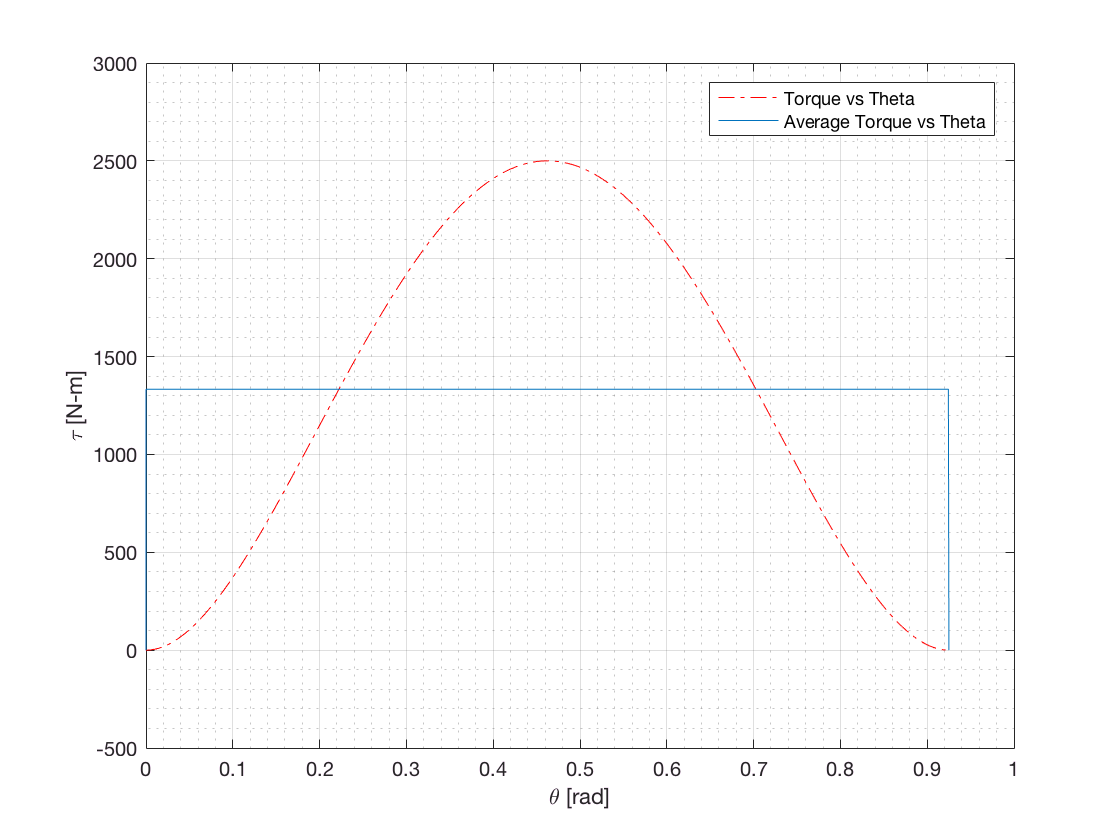

figure('Name','Torque/AverageTorque vs theta')
plot(thetaPress,torquePress,'r-.',[0,thetaPress,0.9250245036],averageTorqueArray)
legend('Torque vs Theta','Average Torque vs Theta')
xlabel('\theta [rad]')
ylabel('\tau [N-m]')
grid on
grid minor

The power transmitted will be approximated using the average torque as,


$$\bar T \omega_{ave} = P$$


Therefor, this linear approximation results in the average power transmitted. However, peak motor power can be estimated by presuming that peak torque occurs at the average angular velocity. 


$$T_{max} \omega_{ave} = P_{peak}$$


Power_ave = averageTorque*omega_ave; disp(['Average Power: ',num2str(Power_ave/1000),' kW'])

Average Power: 12.9334 kW


Power_peak = max(torquePress)*omega_ave; disp(['Peak Power: ',num2str(Power_peak/1000),' kW'])

Peak Power: 24.253 kW


As seen, the maximum power draw exceeds the 20 kW while the motor supplies 12.9334 on average. This power is used to store energy in the Flywheel. We presume the FlyWheel is made from Cast Iron. The thickness will be assumed to be 57 mm.


$$\rho = 7800 ~kg/m^3$$


The process will be solved as,


$$m = \frac{\pi d^2 t \rho}{4}\\ \\

I = 43.68 kg-m^2 = \frac{md^2}{8}\\

m*d^2 = 349.44 \\

m = \frac{349.44}{d^2}\\

\frac{\pi d^2 t \rho}{4}=\frac{349.44}{d^2}\\

d = (\frac{1397.8}{\pi (57/1000) 7800})^{0.25}$$


th = (57/1000);
cost = 1.42; % USD/kg
rho = 7800;
FlyWheeld = (1397.8/(pi*th*rho))^0.25;
m = (pi*(FlyWheeld^2)*th*rho)/4; 
disp(['d = ', num2str(1000*round(FlyWheeld,2)),' mm'])

d = 1000 mm


disp(['m = ', num2str(round(m,2)),' kg'])

m = 349.32 kg


disp(['cost = $', num2str(round(m*cost,2))])

cost = $496.03


In order to visualize the flywheel,

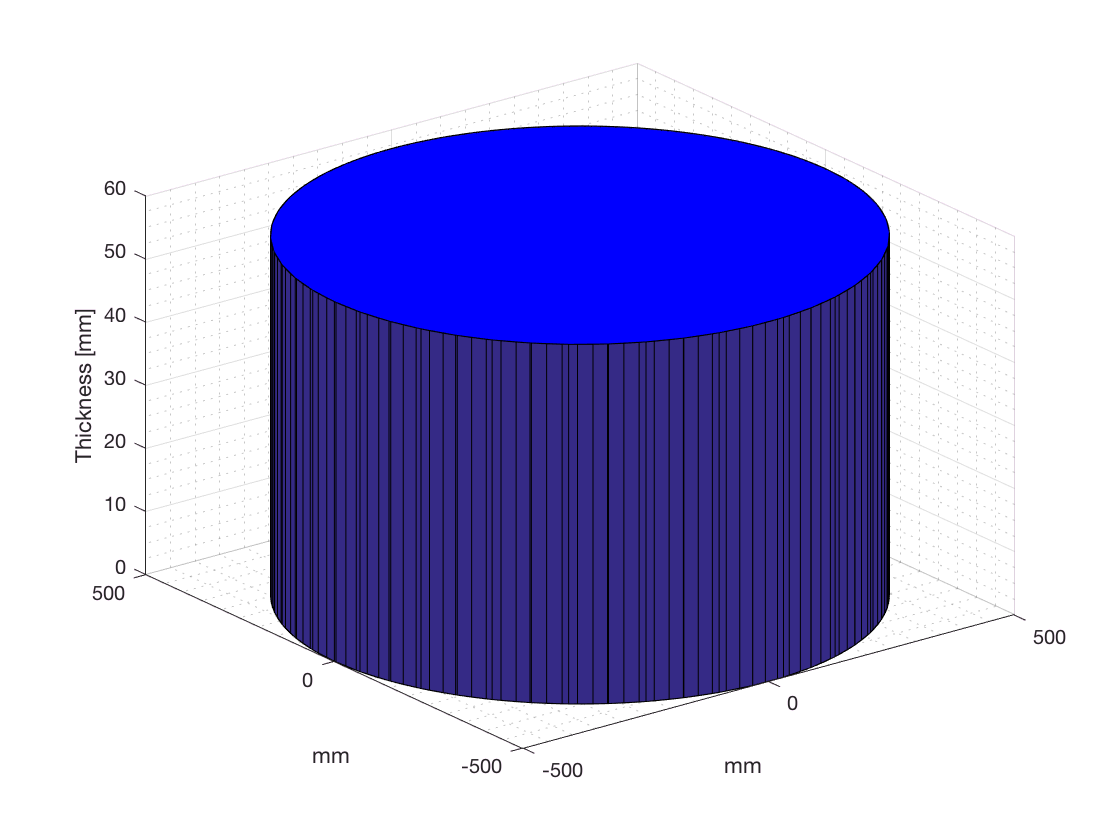

r = round(1000*FlyWheeld^2/2);
h = round(th*1000);
angle = 0:0.05:2*pi;
x = r*cos(angle);
y = r*sin(angle);
y(end) = 0;
z1 = 0;
z2 = h;
[X,Y,Z] = cylinder(1000/2,50);
Z(2,:)=57;
figure('Name','Flywheel')
surf(X,Y,Z); hold on
xlabel('mm')
ylabel('mm')
zlabel('Thickness [mm]')
grid on
grid minor
patch(x,y,z1*ones(size(x)),'b'); hold on
patch(x,y,z2*ones(size(x)),'b'); hold on
surf([x;x],[y;y],[z1*ones(size(x));z2*ones(size(x))]); hold on

## Gear Definition

The gears employed will be Helical Gears. 

The first gear pair (connected to the crankshaft) will be defined as a 17 tooth pinion driving a 34 tooth gear. Th middle pair will be designed to be identical to the first gear pair given the identical reduction. The last reduction will feature a 20 tooth tooth pinion driving a 55 tooth gear. Bringing back the previously worked equations,


$${N_2}=2{N_1}\\

{N_4}=2{N_3}\\

{N_6}=2.75{N_5}\\ \\

{N_1}={N_3}\\
{N_3}=1.25{N_5}\\$$


Following this notation,


$$N_1 = 17\\
N_2 = 34\\
N_3 = 17\\
N_4 = 34\\
N_5 = 20\\
N_6 = 55\\$$


The pitch diameter can be computed by setting the following values for the module,


$$m_6 = 2\\
m_4 = 8\\
m_2 = 10\\$$


From these values, the pitch diameter can be easily obtained as,


$$d_2 = 10*34=340~mm\\
d_1 = d_2/2 = 170~mm\\
d_4 = 34*8 = 272~mm\\
d_3 = d_4/2 = 136~mm\\
d_6 = 2*55 = 110~mm\\
d_5 = d_6/2.75 = 40\\$$


The following modules are computed from the resulting diameters,


$$m_5 = 2 \\
m_3 = 8 \\
m_1 = 10\\$$


N1 = 17; 
N3 = N1; 
N2 = FirstReduction*N1;
N4 = N2;
N5 = 20;
N6 = ThirdReduction*N5;
m6 = 2;
m4 = 8;
m2 = 10;
d2 = m2*N2;
d1 = d2/FirstReduction;
d4 = m4*N4;
d3 = d4/SecondReduction;
d6 = m6*N6;
d5 = d6/ThirdReduction;
m1 = d1/N1;
m3 = d3/N3;
m5 = d5/N5;
P1 = N1/d1;
P2 = N2/d2;
P3 = N3/d3;
P4 = N4/d4;
P5 = N5/d5;
P6 = N6/d6;

These quantities will be vectorized to facilitate future computing,

P = [P1, P2, P3, P4, P5, P6];
m = [m1, m2, m3, m4, m5, m6];
N = [N1, N2, N3, N4, N5, N6]

N =     17    34    17    34    20    55


d = [d1, d2, d3, d4, d5, d6]

d =    170   340   136   272    40   110


The addendum and dedendum can be easily computed through the following relationships for Helical Gears:


$$a = \frac{1.00}{P_n}\\

b = \frac{1.25}{P_n}$$


a = 1.00.*m; % Addendum
b = 1.25.*m; % Dedendum
p = pi./P;   % circular pitch
t = p./2;    % tooth thickness
c = b-a;     % clearance

The helical and pressure will be explicitly labeled to provide a general framework.

helicalAngle = 0;   % Deg
pressureAngle = 20; % Deg
P = P.*cosd(helicalAngle)

P =     0.1000    0.1000    0.1250    0.1250    0.5000    0.5000


m = m.*cosd(helicalAngle)

m =     10    10     8     8     2     2


The pitch diameter can be generalized to:

pitchDiameter = N./(P.*cosd(helicalAngle))

pitchDiameter =    170   340   136   272    40   110


The base diameter can also be generalized to:

baseDiameter = d.*cosd(pressureAngle)

baseDiameter =   159.7477  319.4955  127.7982  255.5964   37.5877  103.3662


Other relevant quantities include,

- Standard center distance


$$SCD = \frac{D+d}{2}$$


SCD = (d(1:2:6)+d(2:2:6))/2

SCD =    255   204    75


- Outside Diameter


$$OD = D+2a$$


OD = d+2*a

OD =    190   360   152   288    44   114


- Root Diameter


$$RD = D-2b$$


RD = d-2*b

RD =    145   315   116   252    35   105


- Base helix angle


$$\tan^{-1}(\tan(\psi)\cos(\phi))$$


BHA = atand(tand(helicalAngle).*cosd(pressureAngle))

BHA = 0